# Семинар 4. Контейнеры для работы с разнотипными данными (продолжение)

- Таблицы

- Множества

- Словари

- Использование контейнеров java

Небольшой пример по использованию структур и функции **{:}** из предыдущего семинара 

Конструктор объекта типа **struct **имеет следующую форму:

**struct("field1_name",value1,...."fieldN_name",valueN)**

Для конструкирования структуры с заданными именами полей можно использовать возможности "splat" - функции ячеек.

Для примера создадим стурктуру с именами полей от 'a' до 'y' и значениями  в этих полях от 1 до 25

clearvars
field_names = arrayfun(@string,'a':'y');
n = numel(field_names);
Name_Values_cell = cell(1,2*n); % создаем пустой массив ячеек, 
% в него будут поочередно добавлены имена полей и их значения

% заплоняем имена полей
Name_Values_cell(1:2:end) = cellstr(field_names); % cellstr - преобразует массив string в ячейку массивов char
Name_Values_cell

Name_Values_cell = 1×50 cell array
    {'a'}    {0×0 double}    {'b'}    {0×0 double}    {'c'}    {0×0 double}    {'d'}    {0×0 double}    {'e'}    {0×0 double}    {'f'}    {0×0 double}    {'g'}    {0×0 double}    {'h'}    {0×0 double}    {'i'}    {0×0 double}    {'j'}    {0×0 double}    {'k'}    {0×0 double}    {'l'}    {0×0 double}    {'m'}    {0×0 double}    {'n'}    {0×0 double}    {'o'}    {0×0 double}    {'p'}    {0×0 double}    {'q'}    {0×0 double}    {'r'}    {0×0 double}    {'s'}    {0×0 double}    {'t'}    {0×0 double}    {'u'}    {0×0 double}    {'v'}    {0×0 double}    {'w'}    {0×0 double}    {'x'}    {0×0 double}    {'y'}    {0×0 double}


% заполняем содержимое ячеек
Name_Values_cell(2:2:end) = num2cell(1:n); %
Name_Values_cell

Name_Values_cell = 1×50 cell array
    {'a'}    {[1]}    {'b'}    {[2]}    {'c'}    {[3]}    {'d'}    {[4]}    {'e'}    {[5]}    {'f'}    {[6]}    {'g'}    {[7]}    {'h'}    {[8]}    {'i'}    {[9]}    {'j'}    {[10]}    {'k'}    {[11]}    {'l'}    {[12]}    {'m'}    {[13]}    {'n'}    {[14]}    {'o'}    {[15]}    {'p'}    {[16]}    {'q'}    {[17]}    {'r'}    {[18]}    {'s'}    {[19]}    {'t'}    {[20]}    {'u'}    {[21]}    {'v'}    {[22]}    {'w'}    {[23]}    {'x'}    {[24]}    {'y'}    {[25]}


st = struct(Name_Values_cell{:}) % конструктор структур поддерживает произвольное число аргументов

st = struct with fields:
    a: 1
    b: 2
    c: 3
    d: 4
    e: 5
    f: 6
    g: 7
    h: 8
    i: 9
    j: 10
    k: 11
    l: 12
    m: 13
    n: 14
    o: 15
    p: 16
    q: 17
    r: 18
    s: 19
    t: 20
    u: 21
    v: 22
    w: 23
    x: 24
    y: 25




st.y

ans = 25

#### тип table

Для хранения данных в табличках с именами столбцов

clearvars
folder = get_folder()

folder = 'E:\projects\matlab-seminar\basics\sem1_4'

full_file = fullfile(folder,"tbl.xls")

full_file = "E:\projects\matlab-seminar\basics\sem1_4\tbl.xls"

cell_1 = cell(21,6);
cell_1(2:end,:) = num2cell(rand([20 6]));
cell_1(1,:) = {"а" "ё" "а" "а" "и" "л" };
writecell(cell_1,full_file);
tbl1 = readtable(full_file); 

% можно читать таблички из эксель или текстовых файлов с разделителем, например, .csv
% readtable - высокоуровневая читалка с очень большим набором функций
help("readtable")

 readtable Create a table by reading from a file.
 
    Use the readtable function to create a table by reading column-oriented
    data from a file. readtable automatically determines the file format
    from its extension as described below.
 
    T = readtable(FILENAME) creates a table by reading from a file, where
    FILENAME can be one of these:
 
        - For local files, FILENAME can be a full path that contains
          a filename and file extension. FILENAME can also be a relative
          path to the current folder, or to a folder on the MATLAB path.
          For example, to import a file on the MATLAB path:
 
             T = readtable("patients.xls");
 
        - For files from an Internet URL or stored at a remote location,
          FILENAME must be a full path using a Uniform Resource Locator
          (URL). For example, to import a remote file from Amazon S3,
          specify the full URL for the


% функции, которые работают с объектами типа таблица
methods(tbl1)

Methods for class table:

abs           acos          acosd         acosh         acot          acotd         acoth         acsc          acscd         acsch         addprop       addvars       and           asec          asecd         asech         asin          asind         asinh         atan          atan2         atan2d        atand         atanh         cat           ceil          convertvars   cos           cosd          cosh          cospi         cot           cotd          coth          csc           cscd          csch          cummax        cummin        cumprod       cumsum        diff          eq            exp           expm1         fix           floor         ge            gt            horzcat       inner2outer   innerjoin     intersect     isempty       ismember      isprop        issortedrows  istable       istabular     join          keyHash       keyMatch      ldivide       le            log           log10         log1p         log2          lt            max     


tbl1.Properties.VariableNames = {'name' 'a1' 'a2' 'a3' 'a4' 'a5'}

tbl1 = 20×6 table
      name        a1         a2          a3           a4           a5   
    ________    _______    _______    _________    _________    ________

    0.097422    0.39133    0.55511      0.12773      0.54513     0.61884
     0.32388     0.8838    0.92771      0.83008      0.39674     0.57905
     0.74223    0.39278    0.96309      0.20531      0.46609     0.60153
     0.70525    0.31148    0.13124      0.29816      0.85957     0.46227
     0.15624    0.97398    0.33272      0.70097    0.0082674     0.39246
     0.44545    0.82648    0.57807      0.09761      0.85654    0.091467
     0.65643       0.27      0.275      0.60798      0.61964     0.98576
    0.086457    0.79208    0.56191      0.61249     0.048781     0.37888
    0.035483    0.10157     0.8469      0.98101

mean_val = mean(tbl1(:,2:end)) % среднее значение 

mean_val = 1×5 table
      a1         a2         a3         a4         a5  
    _______    _______    _______    _______    ______

    0.53222    0.55043    0.47252    0.49234    0.5476


standard_deviation=std(tbl1(:,2:end)) % среднее значение 

standard_deviation = 1×5 table
      a1         a2         a3         a4         a5   
    _______    _______    _______    _______    _______

    0.29102    0.26721    0.31474    0.32872    0.30301


summary(tbl1)

Variables:

    name: 20×1 double

        Properties:
            Description:  а
        Values:

            Min       0.0046851
            Median      0.38467
            Max         0.98901

    a1: 20×1 double

        Properties:
            Description:  ё
        Values:

            Min       0.10157 
            Median    0.55872 
            Max       0.97398 

    a2: 20×1 double

        Properties:
            Description:  а
        Values:

            Min       0.042565
            Median     0.55851
            Max        0.96309

    a3: 20×1 double

        Properties:
            Description:  а
        Values:

            Min       0.0068895
            Median      0.51206
            Max         0.98101

    a4: 20×1 double

        Properties:
            Description:  и
        Values:

            Min       0.0082674
            Median      0.51567
            Max         0

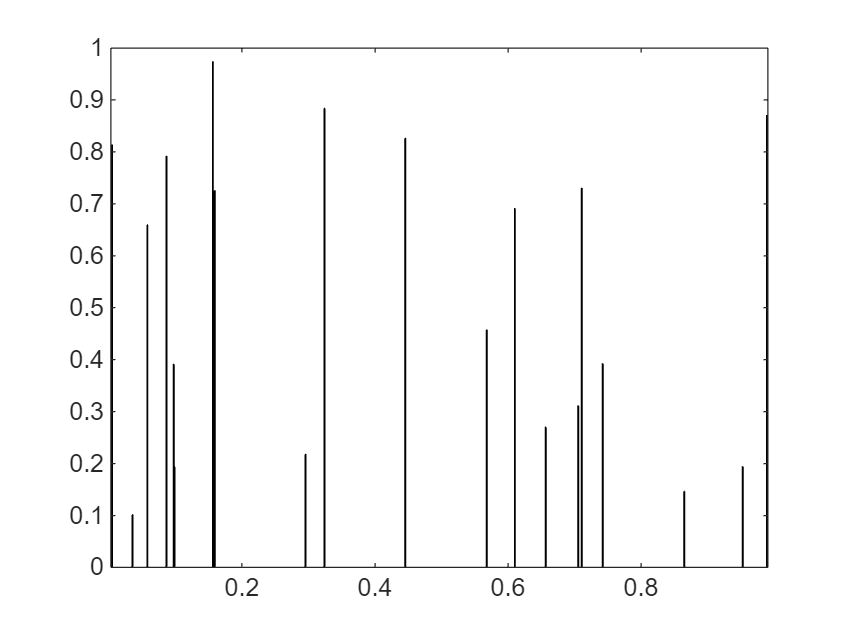

bar(tbl1.name,tbl1.a1)

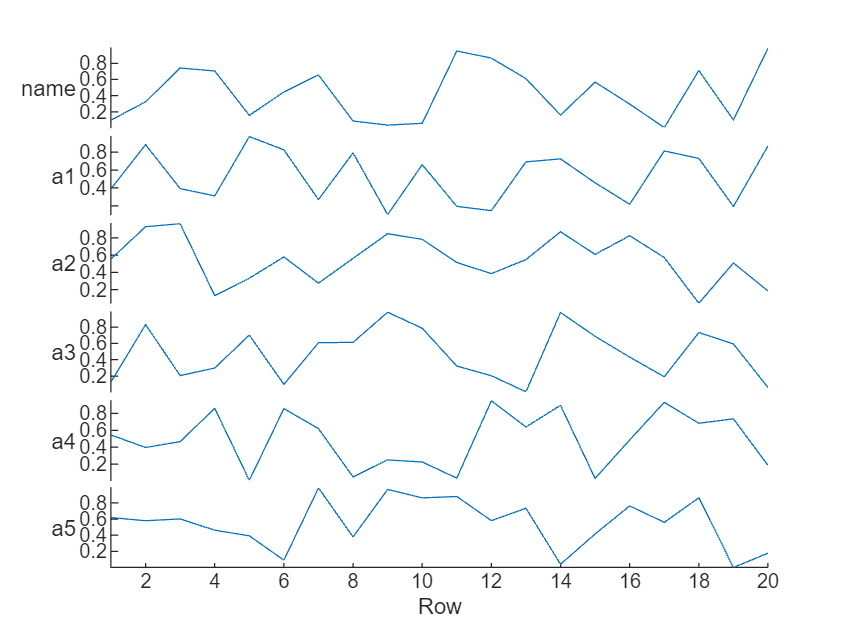

stackedplot(tbl1)

%tbl2 = table([1:4]',ones(4,3,2),eye(4,2))  - элементы разной размерности
%работают но не отображаюстя в LiveScript


#### тип containers.Map

Для хранения разнородных данных по имени (ключу)

clearvars
M = containers.Map('KeyType','char','ValueType','double')


M = 

  Map with properties:

        Count: 0
      KeyType: char
    ValueType: double



M("a")=10

M =   Map with properties:

        Count: 1
      KeyType: char
    ValueType: double


methods(M)

Methods for class containers.Map:

Map      disp     isKey    isempty  keys     length   remove   size     values   

Static methods:

empty    

Methods of containers.Map inherited from handle.



#### тип dictionary (рекомендуется вместо containers.Map)

Для хранения и получения данных по "ключу"

clearvars
d =  dictionary(["sin" "cos" "tan"],{@sin, @cos, @tan})


d =

  dictionary (string ⟼ cell) with 3 entries:

    "sin" ⟼ {@sin}
    "cos" ⟼ {@cos}
    "tan" ⟼ {@tan}



d("sin")

ans = 1×1 cell array
    {@sin}


d1 = d("sin")

d1 = 1×1 cell array
    {@sin}


d1{1}(pi)

ans = 1.2246e-16

d("cot") = {@cot}


d =

  dictionary (string ⟼ cell) with 4 entries:

    "sin" ⟼ {@sin}
    "cos" ⟼ {@cos}
    "tan" ⟼ {@tan}
    "cot" ⟼ {@cot}




d2 = dictionary({[false true true] [true false true] [true true false]},{@sin, @cos, @tan}) 


d2 =

  dictionary (cell ⟼ cell) with 3 entries:

    {[0 1 1]} ⟼ {@sin}
    {[1 0 1]} ⟼ {@cos}
    {[1 1 0]} ⟼ {@tan}



% можно в качестве ключей использовать массивы
fun = d2({[true true false]})

fun = 1×1 cell array
    {@tan}


fun{1}(pi)

ans = -1.2246e-16

#### Итерирование по коллекциям

Циклы могут перебирать элементы коллекций (но только родных джавовских не могут)

% итерирование по ячейкам
A_cell = {1,2,3}

A_cell = 1×3 cell array
    {[1]}    {[2]}    {[3]}


for a = A_cell
    class(a)
    disp(a{1})
end

ans = 'cell'

     1



ans = 'cell'

     2



ans = 'cell'

     3





% итерирование по структурам
A_struct(3) = struct('f1',3);
A_struct(1).f1 = 1;A_struct(2).f1 = 2;

for st = A_struct
    disp("st(i)=" + st.f1)
end

st(i)=1
st(i)=2
st(i)=3



%итерирование по словарям

A_dict = dictionary(["a" "b" "c"],[1 2 3])


A_dict =

  dictionary (string ⟼ double) with 3 entries:

    "a" ⟼ 1
    "b" ⟼ 2
    "c" ⟼ 3



try
    for d = A_dict
        d
    end
catch Ex
    "ss"
end

ans = "ss"

i = 0;
for key = keys(A_dict)'
    i = i+1
    disp("key => value:  " + key+"=>"+ A_dict(key))
end

i = 1

key => value:  a=>1


i = 2

key => value:  b=>2


i = 3

key => value:  c=>3


A_dict(key)

ans = 3

## Не хватает коллекции уникальных элементов типа множество

#### Вариант 1 методы матлаб для работы с массивами как с множествами

clearvars
A = ["c"  "b" "a" "c"];
B = ["a" "d"];
setdiff(A,B) % Элементы множества A не содержащиеся в множестве B

ans = 1×2 string array
    "b"    "c"


setdiff(A,B,'stable') % чтобы сохранить изначальный порядок элементов в массиве

ans = 1×2 string array
    "c"    "b"


intersect(A,B) % Пересечение двух множеств

ans = "a"

unique(A)

ans = 1×3 string array
    "a"    "b"    "c"


#### Вариант 2: использовать богатый арсенал java ( collections)

Матлаб имеет "встроенный" java 8

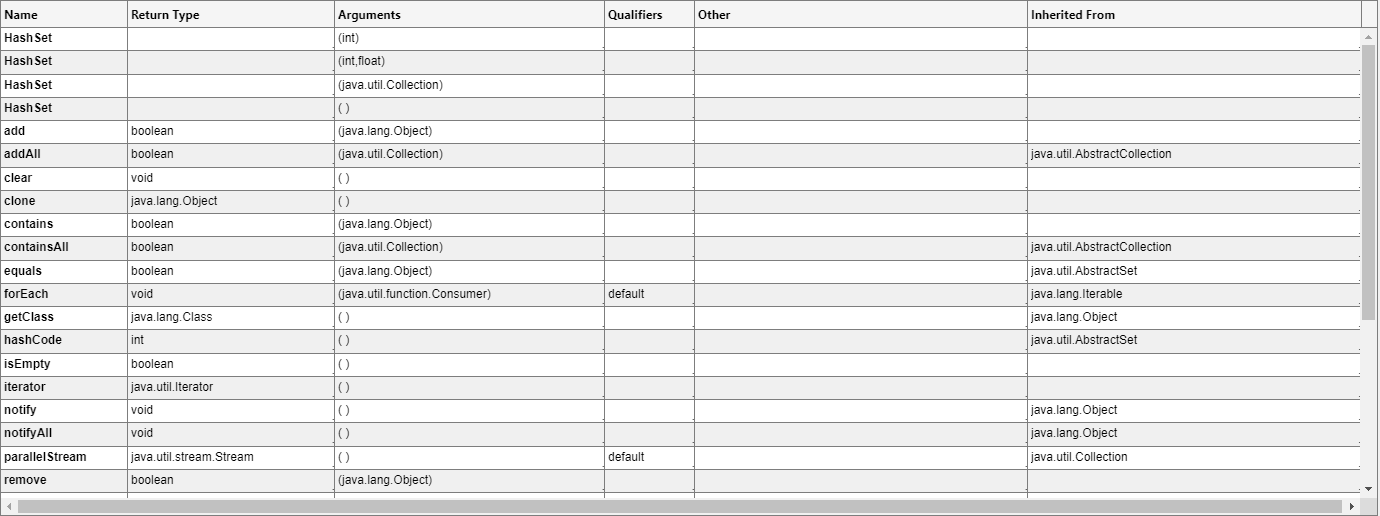

methodsview(java.util.HashSet) % Графическая оболочка для java документации

Пример нахождения пересечения двух множеств

import java.util.HashSet % java.util.* - импортирует все коллекции из джавы 
jA = HashSet; % вызываем конструктор для джава объекта
jB = HashSet; % вызываем конструктор для джава объекта
methods(jA)

Methods for class java.util.HashSet:

HashSet         add             addAll          clear           clone           contains        containsAll     equals          forEach         getClass        hashCode        isEmpty         iterator        notify          notifyAll       parallelStream  remove          removeAll       removeIf        retainAll       size            spliterator     stream          toArray         toString        wait            




A = ["a" "b" "c"];
B = ["a" "d"];

for iii = A
    add(jA,iii) % добавляем элемент в множество jA
end

ans = logical
   1


ans = logical
   1


ans = logical
   1


for iii = B
    add(jB,iii) % добавляем элемент в множество jB
end

ans = logical
   1


ans = logical
   1


unionAB = clone(jA) % клонирует объект (метод java)


unionAB =

[a, b, c]



unionAB.addAll(jB) % функция добавляет элементы множества jB в множество  unionAB

ans = logical
   1



jA


jA =

[a, b, c]



unionAB


unionAB =

[a, b, c, d]




intersectionAB = clone(jA)


intersectionAB =

[a, b, c]



intersectionAB.retainAll(jB)

ans = logical
   1



jA


jA =

[a, b, c]



intersectionAB


intersectionAB =

[a]



Вместо типа dictionary можно использовать java.util.HashMap, это возможно будет работать быстрей (скорее всего) 

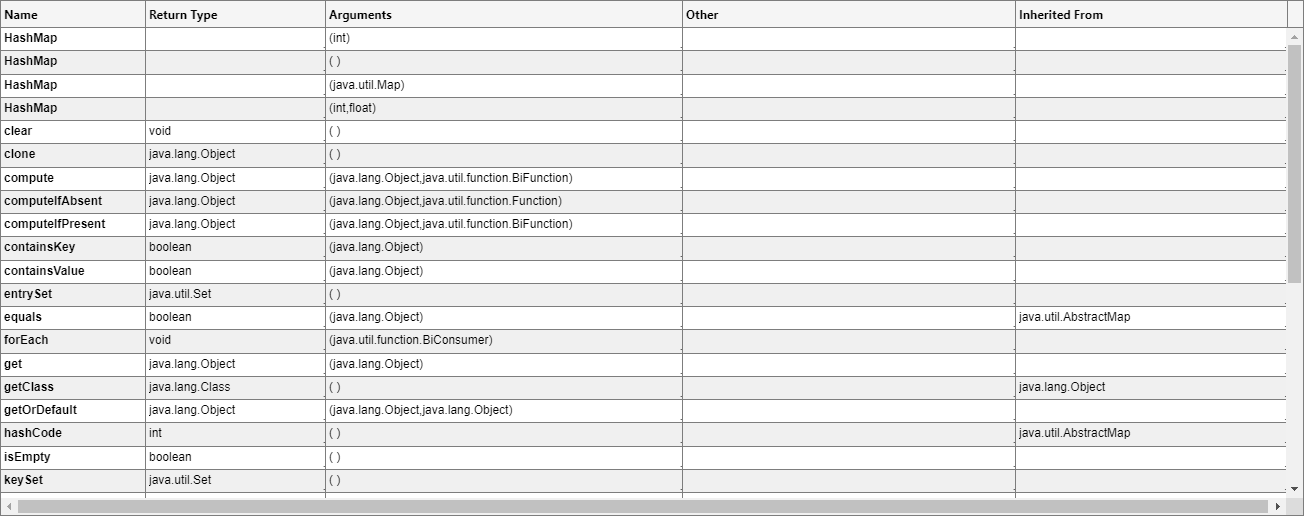

methodsview(java.util.HashMap)

import java.util.HashMap % можно использовать вместо словарей
jMap = java.util.HashMap; % создается объект java с которым напрямую можно работать из матлаб 
methods(jMap)

Methods for class java.util.HashMap:

HashMap           clear             clone             compute           computeIfAbsent   computeIfPresent  containsKey       containsValue     entrySet          equals            forEach           get               getClass          getOrDefault      hashCode          isEmpty           keySet            merge             notify            notifyAll         put               putAll            putIfAbsent       remove            replace           replaceAll        size              toString          values            wait              



jMap.put("a",figure(1));
jMap.put("b",figure(2));
keySet(jMap)


ans =

[a, b]



jMap.get("b") % вытакскиваем число

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


jMap


jMap =

{a=matlab.ui.Figure, b=matlab.ui.Figure}



jArrayObj = jMap.values().toArray()


jArrayObj =

  java.lang.Object[]:

    [matlab_ui_FigureBeanAdapter0]
    [matlab_ui_FigureBeanAdapter0]



methods(jArrayObj)

Methods for class java.lang.Object[]:

equals     getClass   hashCode   notify     notifyAll  toString   wait       



f_array= arrayfun(@(i)jArrayObj(i), 1:jMap.size(),"UniformOutput",false);
f_array{1}

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


function return_value = like_example(be_like_me)
    return_value = zeros(numel(be_like_me),'like',be_like_me);
    return_value = return_value*be_like_me(:);
end
function A = fill_by_row()
    N = 5000;
    A = zeros(N);
    for iii=1:N % внешний цикл перебирает строки
        for jjj=1:N
            A(iii,jjj) = 5;
        end
    end
end
function A = fill_by_column()
    N = 5000;
    A = zeros(N);
    for jjj=1:N % внешний цикл перебирает колонки
        for iii=1:N
            A(iii,jjj) = 5;
        end
    end
end
function A=fill_by_column_no_memalloc()
    N = 5000;
    for jjj=1:N % внешний цикл перебирает колонки
        for iii=1:N
            A(iii,jjj) = 5;
        end
    end    
end
function MAT=fill_by_column_reverse_order()
    N = 5000;
    for jjj=N:-1:1 % внешний цикл перебирает колонки
        for iii=N:-1:1
            MAT(iii,jjj) = 5;
        end
    end    
end

function [r_str,r_ch] = gen_random_string(N)
        alfabeth = 'a':'y';
        n = numel(alfabeth);
        rand_inds = randi(n,[1,N]);
        r_ch = alfabeth(rand_inds);
        r_str = string(r_ch);
end

%% Сравнение операций, выполняемых непосредственно для всей матрицы и перебором элементов матрицы
function A = sin_in_circle(A)
    N = size(A);
    for jjj=1:N(2) % внешний цикл перебирает колонки
        for iii=1:N(1)
            A(iii,jjj) = sin(A(iii,jjj));
        end
    end
end
function A = sin_direct(A)
    A = sin(A);
end
function A = sin_in_circle_line_index(A)
    N = numel(A);
    for iii=1:N
        A(iii) = sin(A(iii));
    end
end
%
function out = ALL(A)
    out = sum(A,'all');
end
% что быстрей итерирование по коллекции или итерирование с индексацией
function s = indexwise_iter() % индексирование по индексам
    A = rand(100000,1);
    s=0;
    for iii = 1:numel(A)
        s = s+ A(iii);
    end
end
function s = elementwise_iter()
    A = rand(100000,1);
    s=0;
    for a = transpose(A)
        s = s+ a;
    end
end
% Пример исопльзования структур типа cell  - функция с произвольным числом
% аргументов
function varar_fun(varargin)
    counter = 0;
    for arg = varargin
        counter = counter + 1;
        disp("arg" + counter);
        disp(arg{1})
    end
end

function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end